## Answer of  Assignment 1

Tan, Shunwen; Purohit, Shreyas ; Mao, Zheng ; Hernandez Sanz, Fernando

## 1.Pricing European Options

% (a) Use inputs:
S0=100; %initial stock price
K=90;   %strike price
r=0.02;  % interest rate
h=0.25;  % length of period
T=4;  % number of period
u= exp(r*h+0.2*sqrt(h)); % up factor
d= exp(r*h-0.2*sqrt(h)); % down factor
% payoff function of European straddle
OpESPayoff  = @(ST,K) max(max(ST - K, 0),max(K - ST, 0));

% Calculates the European stradle initial price and the composition of the
% replicating portfolio at every node of the tree by using function "EuropeanBin" 
[ComBond_a,ComStock_a,OptPrice_a]=EuropeanBin(S0,K,OpESPayoff,r,h,u,d,T);

% Extract the initial price
OptPrice_a(1,1)

ans = 18.4891

% Extract initial composition of the replicating portfolio
[ComBond_a(1,1),ComStock_a(1,1)]

ans =   -35.1958    0.5368



% (b) Use different inputs for T and h:
h1=0.025;  % length of period
T1=40;  % number of period
u1= exp(r*h1+0.2*sqrt(h1)); % up factor
d1= exp(r*h1-0.2*sqrt(h1)); % down factor
% Again calculates the the outputs using function "EuropeanBin"
[ComBond_b,ComStock_b,OptPrice_b]=EuropeanBin(S0,K,OpESPayoff,r,h1,u1,d1,T1);
% Extract the initial price
OptPrice_b(1,1)

ans = 17.7555

% Extract initial composition of the replicating portfolio
[ComBond_b(1,1),ComStock_b(1,1)]

ans =   -35.8782    0.5363



% (c) Calculates the European binary call option initial price
% payoff function of binary call option 
BinCPayoff = @ ( ST,K) 1*(ST>K)+0*(ST<=K);
% Again calculates the the outputs using function "EuropeanBin" with different payoff function
[ComBond_c,ComStock_c,OptPrice_c]=EuropeanBin(S0,K,BinCPayoff,r,h,u,d,T);
% Extract the initial price
OptPrice_c(1,1)

ans = 0.6363

% Extract initial composition of the replicating portfolio
[ComBond_c(1,1),ComStock_c(1,1)]

ans =    -1.2854    0.0192


## 2.Pricing American Options

% Define inputs:
S0_2=10; %initial stock price
K_2=10;   %strike price
r_2=0.01;  % interest rate
ha=1/365;  % length of period 
T_2=250;  % number of period
ua=exp(0.01*ha+0.15*sqrt(ha)); %upward factor
da=exp(0.01*ha-0.15*sqrt(ha)); % downward factor
% payoff function of American call option and put option
OpACPayoff  = @( ST,K,C) max(ST - K, C);
OpAPPayoff  = @( ST,K,P) max(K - ST, P);

% Calculates the initial value of an American put and an American call as well as the composition of the
% replicating portfolio at every node of the tree by using function "AmericanBin" 
% Determines the optimal exercise dates by output "EarlyE"
[ComBond2_c,ComStock2_c,EarlyE_c,OptPrice2_c]=AmericanBin(S0_2,K_2,OpACPayoff,r_2,ha,ua,da,T_2);
[ComBond2_p,ComStock2_p,EarlyE_p,OptPrice2_p]=AmericanBin(S0_2,K_2,OpAPPayoff,r_2,ha,ua,da,T_2);

% Extract the initial price of American call option
OptPrice2_c(1,1)

ans = 0.5286

% Extract initial composition of the replicating portfolio of American call option
[ComBond2_c(1,1),ComStock2_c(1,1)]

ans =    -4.9382    0.5467


% Print the optimal exercise dates of Aemrican call option
% We know that without dividend payment, it is never optimal to early exercise the American call option
    find(any(EarlyE_c==1,1))


ans =

  1×0 empty double row vector



% Extract the initial price of American put option
OptPrice2_p(1,1)

ans = 0.4653

% Extract initial composition of the replicating portfolio of American put option
[ComBond2_p(1,1),ComStock2_p(1,1)]

ans =     5.0660   -0.4601


% Print the optimal exercise dates of American put option
   find(any(EarlyE_p==1,1))

ans =     28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77


## 3. Discrete Dividends

% (a) Define inputs:
S0_3=10; %initial stock price
K_3=10;   %strike price
r_3=0.02;  % interest rate
ha=1/365;  % length of period 
T_3=200;  % number of period
u3=exp(0.2*sqrt(ha));
d3=1/u3;
D=[50,100,150]; %  dividend_times:    
delta=0.05; %  dividend yield
type_A='a'; % the nature of derivative is American

% Calculates the initial prices of an American put and an American call as well as 
% the composition of the replicating portfolio at every node by using function "OptionBin_div" 
% Determines the optimal exercise dates by output "EarlyE"
[ComBond3_c,ComStock3_c,EarlyE3_c,OptPrice3_c]=OptionBin_div(type_A,S0_3,K_3,OpACPayoff,r_3,ha,u3,d3,T_3,D,delta);
[ComBond3_p,ComStock3_p,EarlyE3_p,OptPrice3_p]=OptionBin_div(type_A,S0_3,K_3,OpAPPayoff,r_3,ha,u3,d3,T_3,D,delta);

% Extract the initial price of American call option
OptPrice3_c(1,1)

ans = 0.3399

% Print the optimal exercise dates of Aemrican call option
 find(any(EarlyE3_c==1,1))

ans =     49    99   149



 % Extract the initial price of American put option
OptPrice3_p(1,1)

ans = 1.4560

% Print the optimal exercise dates of Aemrican put option
 find(any(EarlyE3_p==1,1))

ans =    150   151   152   153   154   155   156   157   158   159   160   161   162   163   164   165   166   167   168   169   170   171   172   173   174   175   176   177   178   179   180   181   182   183   184   185   186   187   188   189   190   191   192   193   194   195   196   197   198   199


 
% (b) 
% payoff function of American straddle
OpASPayoff  = @( ST,K,C) max(max(ST - K, C),max( K - ST, C));

% Again apply function "OptionBin_div" to compute the initial price of an American straddle
[ComBond3_s,ComStock3_s,EarlyE3_s,OptPrice3_s]=OptionBin_div(type_A,S0_3,K_3,OpASPayoff,r_3,ha,u3,d3,T_3,D,delta);

% Extract the initial price of American straddle option
OptPrice3_s(1,1)

ans = 1.6420

% Print the optimal exercise dates of Aemrican straddle option
 find(any(EarlyE3_s==1,1))

ans =     49    99   149   150   151   152   153   154   155   156   157   158   159   160   161   162   163   164   165   166   167   168   169   170   171   172   173   174   175   176   177   178   179   180   181   182   183   184   185   186   187   188   189   190   191   192   193   194   195   196


% According to our calculation, we have Straddle < Put + Call
% Because for Straddle, it's a “single” contract with only one exercise; But for the two American 
% option contracts, they have one exercise per option and may happen at different time.
% In this example, we can see that the American call option may early exercise before each ex-dividend 
% date and the put option, on the other hand, after the last dividend payment. So the price of 
% Straddle and Call+Put is not the same.


## 4 Pricing Asian Options by Monte Carlo

% a. Price the option by Monte Carlo simulation using 100,000 paths.
%%% Define parameters 
S0_4 = 200; %initial stock price
K_4 = 220;  %strike
sigma = 0.2; %uncertainty
r_4 = 0.02; %interest rate
T_4 = 1; %time length
N_4 = 365;  %number of period
Npath = 1e6; %number of paths
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Monte Carlo on an arithmetic average price Asian option by using function"Monte_Carlo_AsianOption"
[PriceM,PriceSd,PriceCI]=Monte_Carlo_AsianOption(S0_4,K_4,r_4,sigma,T_4,N_4,Npath);
PriceM

PriceM = 3.2808

% 95 percent confidence interval
PriceCI

PriceCI =     3.2633    3.2983


## 5 Pricing American Options using the Longsta� and Schwartz Least-Square Method

%%% Define parameters 
S0_5 = 200; %initial stock price
K_5 = 220;  %strike
sigma_5 = 0.3; %uncertainty
r_5 = 0.1; %interest rate
T_5 = 1; %time length
N_5 = 250;  %number of period
Npath = 1e6; %number of paths
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% (a)Price American put option via Longstaff-Schwartz Method
[PriceLSM,CF,S,t]=AmericanOptLSM(S0_5,K_5,r_5,T_5,sigma_5,N_5,Npath);
PriceLSM

PriceLSM = 27.5990


% (b)price the option when the number of paths takes the values 10, 100, 1,000, 10,000, and 100,000.
% We can see from the figure that the price converge when number of paths increase
for k = 1:4
Np(k) = 10^k;
NLSM(k)=AmericanOptLSM(S0_5,K_5,r_5,T_5,sigma_5,N_5,Np(k));
Np(5) = 10^5;NLSM(5)=PriceLSM;
end
figure
plot(log10(Np),NLSM,'b-o');
title(' Plot Npath against Price')
xlabel('Number of paths')
ylabel('Eestimated price')

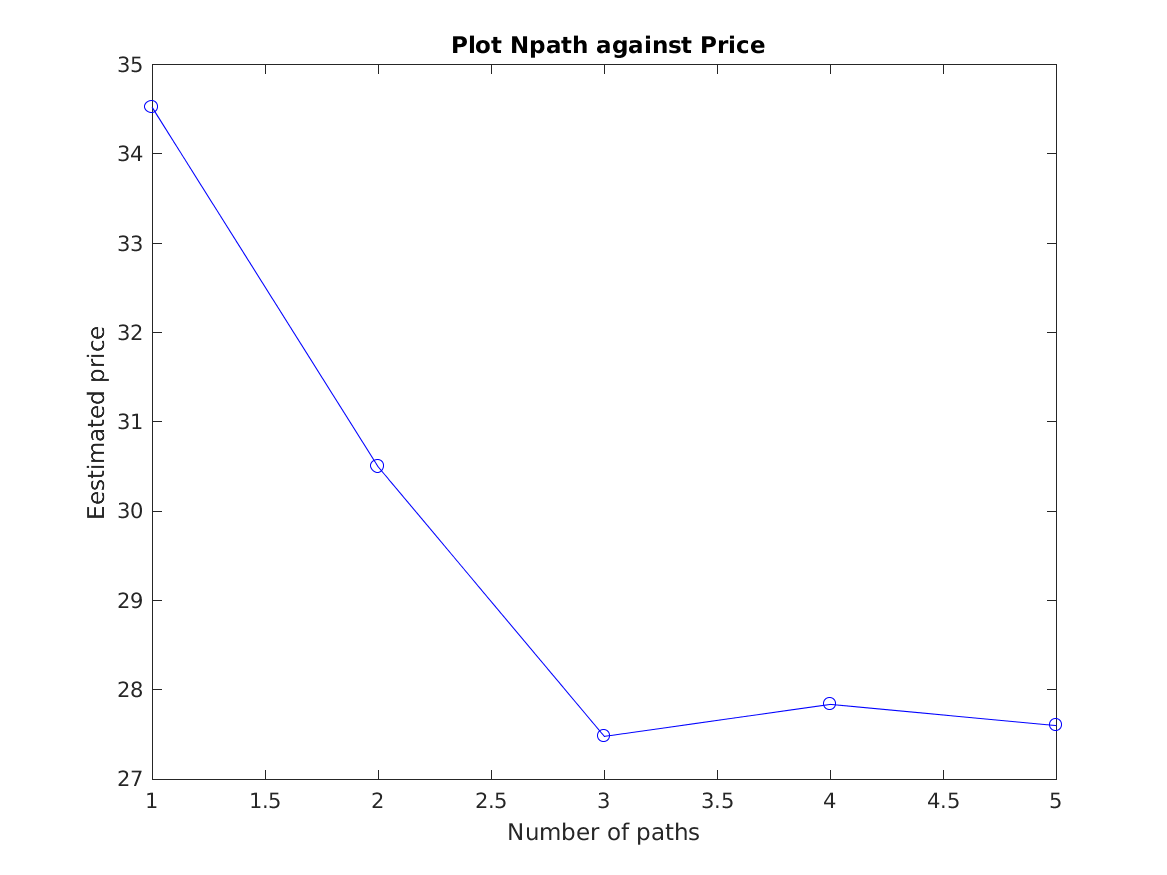


% price the option when the number of steps N takes the values 3, 10, 100, 250, and 1,000.
% We can also see from the figure that the price converge when number of steps increase
Nn = [3,10,100,250,1000];
for k = 1:5
NnLSM(k)=AmericanOptLSM(S0_5,K_5,r_5,T_5,sigma_5,Nn(k),Npath);
end
figure
plot(NnLSM,'b-o');
title(' Plot Nstep against Price')
xlabel('Number of steps')
ylabel('Eestimated price')